clear
clc
%%%%%%%%%%%%%%% Solenoide %%%%%%%%%%
k=1e-07; %Miu0/4pi
miu0=pi*4e-07;% Constante de permitibidad magnetica en el vacio
n=35; %numero de atomos en el polo
anchom=input('Introduce el ancho del iman:');  %ancho del iman
sizem=input('Introduce la distancia entre los polos:');% Longitud del iman
B=input('Introduce los teslas del iman:');% Campo magnetico
miu1=(B*sizem*anchom^2)/miu0 ; %Momento magnetico del iman
ps=(miu1*sizem); %Fuerza del polo
lambda=(ps)/(n^2); %Fuerza de polo de cada atomo en la parte Norte
lambda1=-(ps)/(n^2);%%Fuerza de polo de cada atomo en la parte sur



% Creacion de atomos en cada polo
xx=linspace(-anchom/2,anchom/2,n);
yy=linspace(0,sizem/2,n);

[xqn1,yqn1]=meshgrid(xx,yy);
plot(xqn1,yqn1,'r*') %Graficacion de los atomos en el polo norte
axis equal
hold on
qn1=ones(size(xqn1)).*lambda; %Asigancion de fuerza de polo a cada atomo 


yyy=linspace(-sizem/2,0,n);
[xqn2,yqn2]=meshgrid(xx,yyy)

xqn2 =    -0.0035   -0.0033   -0.0031   -0.0029   -0.0027   -0.0025   -0.0023   -0.0021   -0.0019   -0.0016   -0.0014   -0.0012   -0.0010   -0.0008   -0.0006   -0.0004   -0.0002         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035
   -0.0035   -0.0033   -0.0031   -0.0029   -0.0027   -0.0025   -0.0023   -0.0021   -0.0019   -0.0016   -0.0014   -0.0012   -0.0010   -0.0008   -0.0006   -0.0004   -0.0002         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035
   -0.0035   -0.0033   -0.0031   -0.0029   -0.0027   -0.0025   -0.0023   -0.0021   -0.0019   -0.0016   -0.0014   -0.0012   -0.0010   -0.0008   -0.0006   -0.0004   -0.0002         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0019    0.0021    0.0023 

yqn2 =    -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192
   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187   -0.0187
   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181   -0.0181 

plot(xqn2,yqn2,'b*')%Graficacion de los atomos en el polo sur
qn2=ones(size(xqn2)).*lambda1; %Asigancion de fuerza de polo a cada atomo



%Meshgrid, asignación puntos en el espacio
n2=sizem*5;
bx=linspace(-anchom/2-n2,anchom/2+n2,n);
By=linspace(-sizem/2-n2,sizem/2+n2,n);
[X,Y]=meshgrid(bx,By);
x3=X;
y3=Y;

distx=[]; %Distancias en x
disty=[]; %Distancias en y
num1=[]; %Parte de arriba de la ecuacion del campo magnetico de componentes en x del polo norte
num2=[];%Parte de arriba de la ecuacion del campo magnetico de componentes en y del polo norte
 
p=1;
xqn1=xqn1'

xqn1 =    -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035
   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033
   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031 

xqn2=xqn2'

xqn2 =    -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035
   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033
   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031 

yqn1=yqn1'

yqn1 =          0    0.0006    0.0011    0.0017    0.0023    0.0028    0.0034    0.0040    0.0045    0.0051    0.0057    0.0062    0.0068    0.0074    0.0079    0.0085    0.0091    0.0096    0.0102    0.0108    0.0113    0.0119    0.0125    0.0130    0.0136    0.0142    0.0147    0.0153    0.0159    0.0164    0.0170    0.0176    0.0181    0.0187    0.0192
         0    0.0006    0.0011    0.0017    0.0023    0.0028    0.0034    0.0040    0.0045    0.0051    0.0057    0.0062    0.0068    0.0074    0.0079    0.0085    0.0091    0.0096    0.0102    0.0108    0.0113    0.0119    0.0125    0.0130    0.0136    0.0142    0.0147    0.0153    0.0159    0.0164    0.0170    0.0176    0.0181    0.0187    0.0192
         0    0.0006    0.0011    0.0017    0.0023    0.0028    0.0034    0.0040    0.0045    0.0051    0.0057    0.0062    0.0068    0.0074    0.0079    0.0085    0.0091    0.0096    0.0102    0.0108    0.0113    0.0119    0.0125    0.0130    0.0136    0.0142    0.0147    0.0153    0.0159 

yqn2=yqn2'

yqn2 =    -0.0192   -0.0187   -0.0181   -0.0176   -0.0170   -0.0164   -0.0159   -0.0153   -0.0147   -0.0142   -0.0136   -0.0130   -0.0125   -0.0119   -0.0113   -0.0108   -0.0102   -0.0096   -0.0091   -0.0085   -0.0079   -0.0074   -0.0068   -0.0062   -0.0057   -0.0051   -0.0045   -0.0040   -0.0034   -0.0028   -0.0023   -0.0017   -0.0011   -0.0006         0
   -0.0192   -0.0187   -0.0181   -0.0176   -0.0170   -0.0164   -0.0159   -0.0153   -0.0147   -0.0142   -0.0136   -0.0130   -0.0125   -0.0119   -0.0113   -0.0108   -0.0102   -0.0096   -0.0091   -0.0085   -0.0079   -0.0074   -0.0068   -0.0062   -0.0057   -0.0051   -0.0045   -0.0040   -0.0034   -0.0028   -0.0023   -0.0017   -0.0011   -0.0006         0
   -0.0192   -0.0187   -0.0181   -0.0176   -0.0170   -0.0164   -0.0159   -0.0153   -0.0147   -0.0142   -0.0136   -0.0130   -0.0125   -0.0119   -0.0113   -0.0108   -0.0102   -0.0096   -0.0091   -0.0085   -0.0079   -0.0074   -0.0068   -0.0062   -0.0057   -0.0051   -0.0045   -0.0040   -0.0034 


for i=1:length(xqn1).^2 %Distancias X Y de cada atomo en el polo norte
    distx=[distx;x3-xqn1(i)];
    disty=[disty;y3-yqn1(i)];
    num1=[num1;k.*qn1(i).*distx(p:i*length(bx),1:length(bx))];
    num2=[num2;k.*qn1(i).*disty(p:i*length(bx),1:length(bx))];
    p=(i*length(bx))+1 ; 
end

denom=(distx.^2+disty.^2).^1.5; % Parte de abajo de al ecuacion del campo magnetico
Bxx=num1./denom; % Matriz con todos los componentes x de cada atomo polo norte
Bx=zeros(length(bx),length(bx)); %Matriz donde se sumaran todos los coponentes x de cada atomo polo norte
m=1;
for q=1:length(bx)
    Bx=Bx+Bxx(m:q*length(bx),1:length(bx));%suma
    m=q*length(bx)+1;
end
Byy=num2./denom; % Matriz con todos los componentes y de cada atomo polo norte
By=zeros(length(bx),length(bx));%Matriz donde se sumaran todos los coponentes x de cada atomo polo norte

a=1;
for r=1:length(bx)
    By=By+Byy(a:r*length(bx),1:length(bx));% Suma
    a=r*length(bx)+1;
end

%Parte negativa
% Se efectuan exactamente los mismos caluclos pero con los atomos situados
% en el polo sur del iman
distx2=[];
disty2=[];
num3=[];
num4=[];
h=1

h = 1

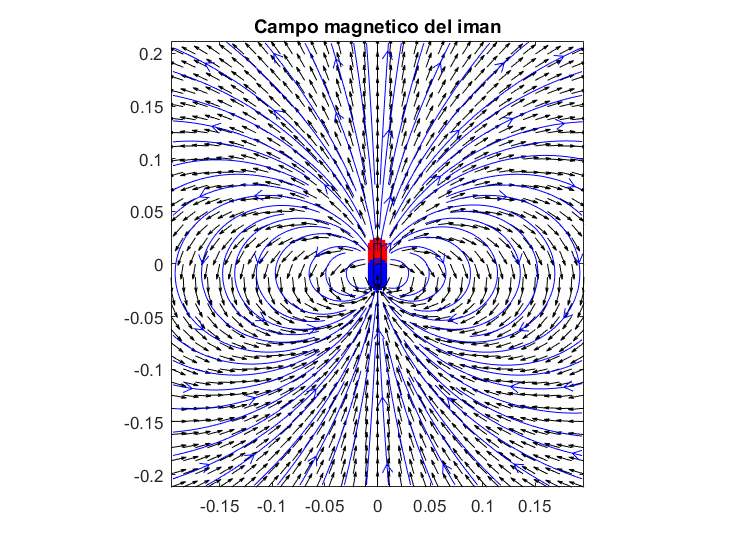

for i2=1:length(xqn2).^2
    distx2=[distx2;x3-xqn2(i2)];
    disty2=[disty2;y3-yqn2(i2)];
    num3=[num3;k.*qn2(i2).*distx2(h:i2*length(bx),1:length(bx))];
    num4=[num4;k.*qn2(i2).*disty2(h:i2*length(bx),1:length(bx))];
    h=(i2*length(bx))+1  ;
end

denom2=(distx2.^2+disty2.^2).^1.5;
Bxx2=num3./denom2;
Bx2=zeros(length(bx),length(bx));

u=1;
for i3=1:length(bx)
    Bx2=Bx2+Bxx2(u:i3*length(bx),1:length(bx));
    u=i3*length(bx)+1;
end
Byy2=num4./denom2;
By2=zeros(length(bx),length(bx));
v=1;
for i4=1:length(bx)
    By2=By2+Byy2(v:i4*length(bx),1:length(bx));
    v=i4*length(bx)+1;
end

%%%%%%% Superposicion de la matriz con coponentes x y de los polos norte y sur%
bx=Bx+Bx2;
by=By+By2;
mb=sqrt(bx.^2+by.^2); %magnitud de los vectores
bx1=bx./mb; % Vectores unitarios
by1=by./mb;

quiver(X,Y,bx1,by1,'k')%Graficacion del campo vectorial magnetico
title('Campo magnetico del iman')
hold on

streamslice(X,Y,bx1,by1) %Lineas de campo magnetico

% Polo Norte
norte = polyshape([-anchom/2,-anchom/2,anchom/2,anchom/2],[sizem/2,0,0,sizem/2]);
plot(norte,'FaceColor','red')
axis equal

% Polo Sur
sur = polyshape([-anchom/2,-anchom/2,anchom/2,anchom/2],[0,-sizem/2,-sizem/2,0]);
plot(sur,'FaceColor','blue','FaceAlpha',0.1)
axis equal
xlim([-anchom/2-n2,anchom/2+n2])
ylim([-sizem/2-n2,sizem/2+n2])